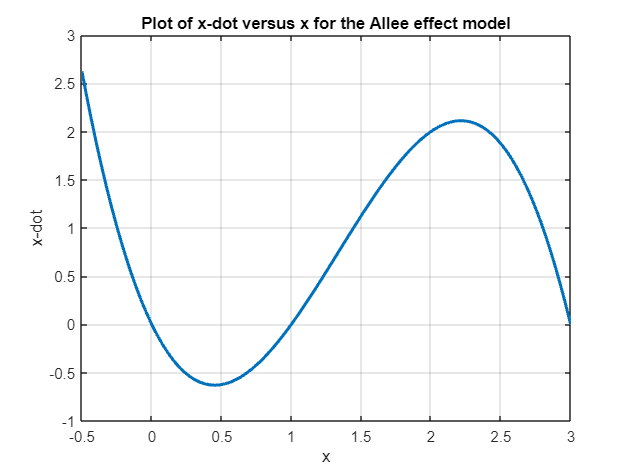

% Define the parameters
a = 1;
b = 2;
r = 1;

% Define the model equation
dxdt = @(x) x .* (r - a * (x - b).^2);
 
% Define the range of x values ;
x = linspace(-0.5, 3, 100);

% Calculate x' values
xdot = dxdt(x);

% Plot x' versus x
plot(x, xdot, 'LineWidth', 2);
xlabel('x');
ylabel('x-dot');
title('Plot of x-dot versus x for the Allee effect model');
grid on;


% Find the fixed points
%fixed_points = [0 2 3];
fixed_points = roots([a, -2*a*b, r]);
fprintf('Fixed points: %f, %f, %f\n', fixed_points);

Fixed points: 3.732051, 0.267949, 

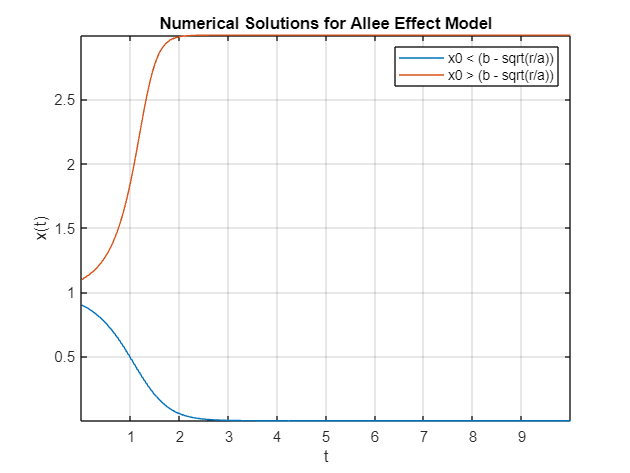


% Define the parameters
a = 1;
b = 2;
r = 1;

% Define the model equation
dxdt = @(x) x .* (r - a * (x - b).^2);

% Define time parameters
delta_t = 0.01;
t_final = 10;

% Initial values
x0_1 = b - sqrt(r/a) - 0.1;
x0_2 = b - sqrt(r/a) + 0.1;

% Euler integration
[t1, x1] = euler_integration(dxdt, x0_1, delta_t, t_final);
[t2, x2] = euler_integration(dxdt, x0_2, delta_t, t_final);

% Plot numerical solutions
figure;
plot(t1, x1, 'DisplayName', 'x0 < (b - sqrt(r/a))');
hold on;
plot(t2, x2, 'DisplayName', 'x0 > (b - sqrt(r/a))');
xlabel('t');
ylabel('x(t)');
title('Numerical Solutions for Allee Effect Model');
legend();
grid on;

function [t, x] = euler_integration(dxdt, x0, delta_t, t_final)
    t = 0:delta_t:t_final;
    x = zeros(size(t));
    x(1) = x0;
    for i = 2:length(t)
        x(i) = x(i-1) + delta_t * dxdt(x(i-1));
    end
end
